Now reading \BME3053C-final-project\trainrats\0trainrat01.jpg


Now reading \BME3053C-final-project\trainrats\0trainrat02.jpg


Now reading \BME3053C-final-project\trainrats\0trainrat03.jpg


Now reading \BME3053C-final-project\trainrats\0trainrat12.jpg


Now reading \BME3053C-final-project\trainrats\0trainrat15.jpg


Now reading \BME3053C-final-project\trainrats\0trainrat20.jpg


Now reading \BME3053C-final-project\trainrats\1trainrat04.jpg


Now reading \BME3053C-final-project\trainrats\1trainrat10.jpg


Now reading \BME3053C-final-project\trainrats\1trainrat11.jpg


Now reading \BME3053C-final-project\trainrats\1trainrat13.jpg


Now reading \BME3053C-final-project\trainrats\1trainrat14.jpg


Now reading \BME3053C-final-project\trainrats\1trainrat16.jpg


Now reading \BME3053C-final-project\trainrats\1trainrat17.jpg


Now reading \BME3053C-final-project\trainrats\1trainrat19.jpg


Now reading \BME3053C-final-project\trainrats\2trainrat05.jpg


Now reading \BME3053C-final-project\trainrats\2trainrat06.jpg


Now reading \BME3053C-final-project\trainrats\2trainrat07.jpg


Now reading \BME3053C-final-project\trainrats\2trainrat08.jpg


Now reading \BME3053C-final-project\trainrats\2trainrat09.jpg


Now reading \BME3053C-final-project\trainrats\2trainrat18.jpg


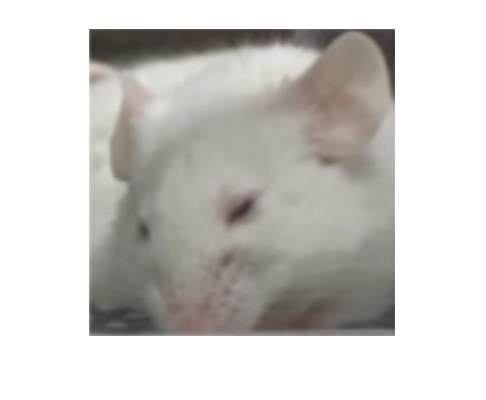

myFolder = '\BME3053C-final-project\trainrats';
if ~isdir(myFolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
  uiwait(warndlg(errorMessage));
  return;
end
filePattern = fullfile(myFolder, '*.jpg');
testrats = dir(filePattern);
for k = 1:length(testrats)
  baseFileName = testrats(k).name;
  fullFileName = fullfile(myFolder, baseFileName);
  fprintf(1, 'Now reading %s\n', fullFileName);
  imageArray = imread(fullFileName);
  imshow(imageArray);  % Display image.
  drawnow; % Force display to update immediately.
end

save testrats;